# Example: Estimate 2-D Target States Using `trackingKF`

## Initialize Estimation Model 

Specify an initial position and velocity for a target that you assume moving in 2-D. The simulation lasts 20 seconds with a sample time of 0.2 seconds.

%rng(2021);    % For repeatable results
dt = 0.2;     % seconds
simTime = 20; % seconds
tspan = 0:dt:simTime;
trueInitialState = [30; 2; 40; 2]; % [x;vx;y;vy]
processNoise = diag([0; 1; 0; 1]); % Process noise matrix

Create a measurement noise covariance matrix, assuming that the target measurements consist of its position states.

measureNoise = diag([4 4]); % Measurement noise matrix

The matrix specifies a standard deviation of 2 meters in both the x- and y-directions. 

Preallocate variables in which to save estimation results.

numSteps = length(tspan);
trueStates = NaN(4,numSteps);
trueStates(:,1) = trueInitialState;
estimateStates = NaN(size(trueStates));

## Obtain True States and Measurements

Propagate the constant velocity model, and generate the measurements with noise. 

F = [1 dt 0  0;
     0  1 0  0; 
     0  0 1 dt;
     0  0 0  1];
H = [1 0 0 0;
     0 0 1 0];
for i = 2:length(tspan)
    trueStates(:,i) = F*trueStates(:,i-1) + sqrt(processNoise)*randn(4,1);  
end
measurements = H*trueStates + sqrt(measureNoise)*randn(2,numSteps);

Plot the true trajectory and the measurements.

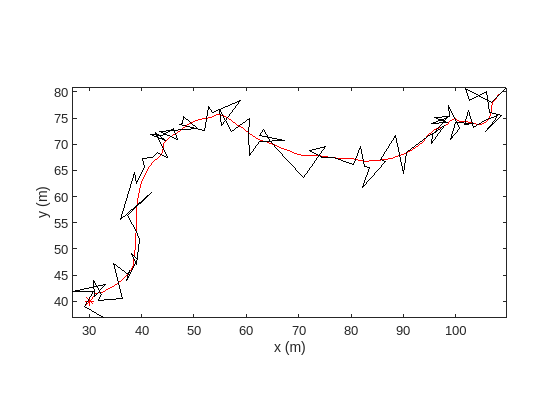

figure
plot(trueStates(1,1),trueStates(3,1),"r*",DisplayName="True Initial")
hold on
plot(trueStates(1,:),trueStates(3,:),"r",DisplayName="Truth")
%plot(measurements(1,:),measurements(2,:),"kx",DisplayName="Measurements")
plot(measurements(1,:),measurements(2,:),"k",DisplayName="Measurements")
xlabel("x (m)")
ylabel("y (m)")
axis image

## Initialize Linear Kalman Filter

Initialize the filter with a state of `[40; 0; 160; 0]`, which is far from the true initial state.  Normally, you can use the initial measurement to construct an initial state as `[measurements(1,1);0 ; measurements(2,1); 0]`. Here, you use an erroneous initial state, which enables you to test if the filter can quickly converge on the truth.

filter = trackingKF(MotionModel="2D Constant Velocity",State=[40; 0; 160;0], ...
    MeasurementModel=H,MeasurementNoise=measureNoise)

filter =   trackingKF with properties:

               State: [4×1 double]
     StateCovariance: [4×4 double]

         MotionModel: '2D Constant Velocity'
        ProcessNoise: [2×2 double]

    MeasurementModel: [2×4 double]
    MeasurementNoise: [2×2 double]

     MaxNumOOSMSteps: 0

     EnableSmoothing: 0


 estimateStates(:,1) = filter.State;

## Run Linear Kalman Filter and Show Results

Run the filter by recursively calling the `predict` and `correct` object functions. From the results, the estimates converge on the truth quickly. In fact, the linear Kalman filter has an exponential convergence speed.

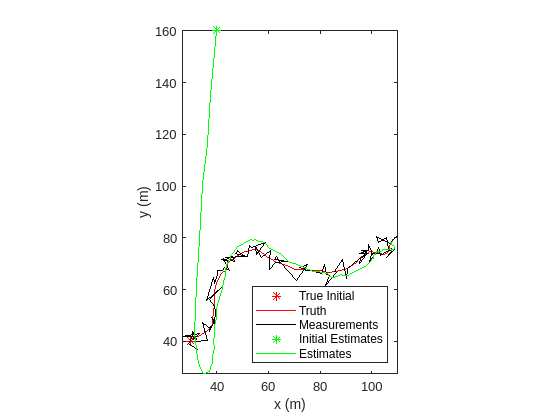

for i=2:length(tspan)
    predict(filter,dt)
    estimateStates(:,i) = correct(filter,measurements(:,i));
end
plot(estimateStates(1,1),estimateStates(3,1),"g*",DisplayName="Initial Estimates")
plot(estimateStates(1,:),estimateStates(3,:),"g",DisplayName="Estimates")
legend(Location="southeast")

*Copyright 2021 The MathWorks, Inc.*